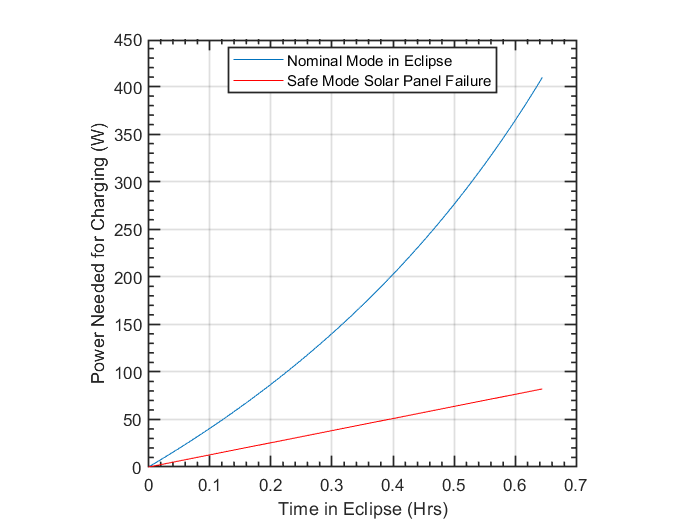

T_o = 1.6 ; %Orbit Time [Hr]
T_e = linspace(0,0.644,100) ; %Eclipse Time [Hr]
T_s = T_o - T_e  ; %Orbit Time [Hr]

C_D_Efficiency = 0.92;
DOD = 0.4;
E_Density = 160; %Energy Density [Whrs/kg]

P = 559.32 ;

P_C = T_e./T_s * (P/C_D_Efficiency);
E_Battery_Capacity = P*T_e / (C_D_Efficiency*DOD);


P_Safe = 117.28 ;

P_C_s = T_e * (P_Safe/C_D_Efficiency);
E_Battery_Capacity_s = P_Safe*T_e / (C_D_Efficiency*DOD);

figure(1)
plot(T_e,P_C)
hold on
plot(T_e,P_C_s,"r")
hold off
xlabel("Time in Eclipse (Hrs)");
ylabel("Power Needed for Charging (W)");

set(gca,'XMinorTick','on')
set(gca,'YMinorTick','on')
set(gca,'TickLength',[0.025 0.025])
set(gca,'LineWidth',1)
grid(gca,'off')  
box(gca,'on')
axis(gca,'square')
grid on
hold off

legend("Nominal Mode in Eclipse","Safe Mode Solar Panel Failure","Location","best")